% parameters
c = 340;        % sound speed
fc = 20e3;      % central frequency
fs = 48000;     % sampling rate
lambda = c/fc;  % wavelength
duration = 1;   % duration time
Nr = 8;         % # of antenna element of Rx
radius = 0.02;  % array radius (m)
Ns = 1;         % # source signal
noisePwr = 1e-4; % noise power

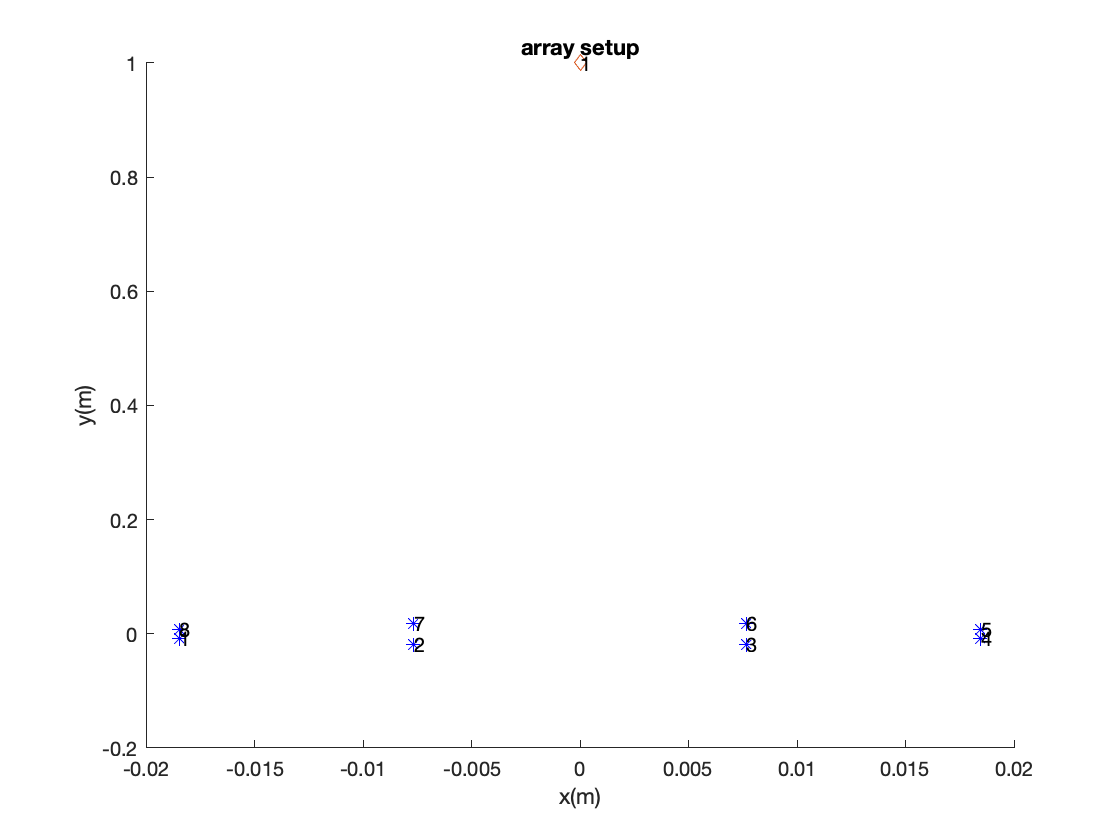

% Define a Uniform Microphone Array
microphone = phased.OmnidirectionalMicrophoneElement('FrequencyRange',[20 20e3]);
rxarray = phased.UCA('NumElements', Nr ,'Radius', radius, "Element", microphone);
pos = getElementPosition(rxarray);
m_xPos = pos(1,:); % x-coord
m_yPos = pos(2,:); % y-coord
m_zPos = pos(3,:); % z-coord

% Define object position
s_Pos = [0, 1, 0]; % source position in meter

% plot setup
figure; hold on;
for ni = 1:Nr
    scatter(m_xPos(ni),m_yPos(ni),'*','b')
    text(m_xPos(ni),m_yPos(ni),num2str(ni))
end
scatter(s_Pos(1),s_Pos(2),'d')
text(s_Pos(1),s_Pos(2),string(s_Pos(2)))
hold off
title('array setup')
xlabel('x(m)')
ylabel('y(m)')

% Simulate the Received Signals
t = 0:1/fs:duration;
t = t(1:end-1)';

distance = zeros(1, Nr);
r_attn = zeros(1, Nr); % attenuation
r_delay = zeros(1, Nr); % delay
rx = zeros(length(t), Nr);
for i=1:Nr
    X = [s_Pos(1), s_Pos(2); m_xPos(i), m_yPos(i)];
    distance(i) = pdist(X, 'euclidean');
    r_delay(i) = distance(i)/c;
    r_attn(i) = (1/(distance(i)))^2;
    rx(:, i) = r_attn(i)*sin(2*pi*fc* (t + r_delay(i)));
end

% add noise
noise = 0.3 * randn(size(rx));
rxSignal = rx + noise; % adding some noise

% convert to complex data
x = zeros(size(rx));
for mic = 1 : Nr
	x(:,mic) = fftFilterSingleSide(rx(:,mic)',fs,fc-200,fc+200,100);
end
% x = rx;

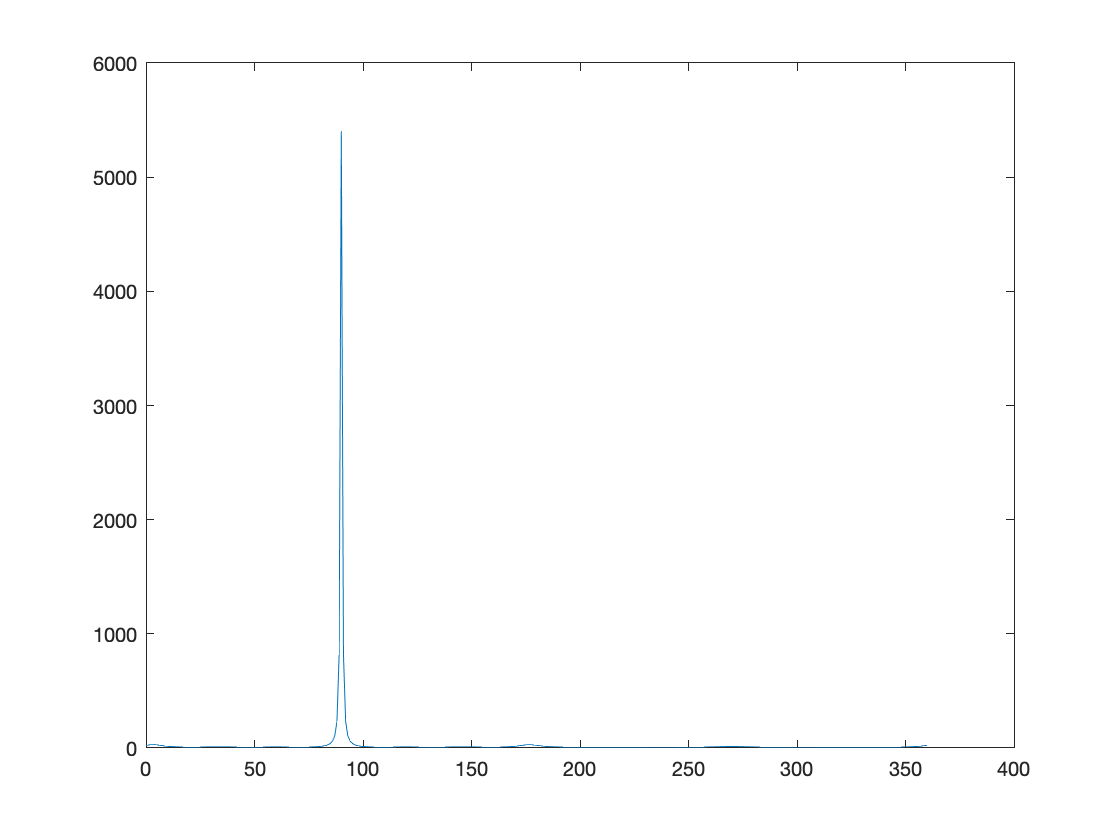

% test AOA
thetaScanningAngles = 0:1:360;
phiScanningAngles = 90;
w = ones(1, Nr)/Nr;
R = x'*x;
escan = steeringVector(m_xPos, m_yPos, m_zPos, fc, c, thetaScanningAngles, phiScanningAngles);
[S_MUSIC, V, Vn] = steeredResponseMusic(R, escan, w, Ns);
figure
plot(thetaScanningAngles, S_MUSIC)

incidentAngle = [90; 90]

incidentAngle =     90
    90


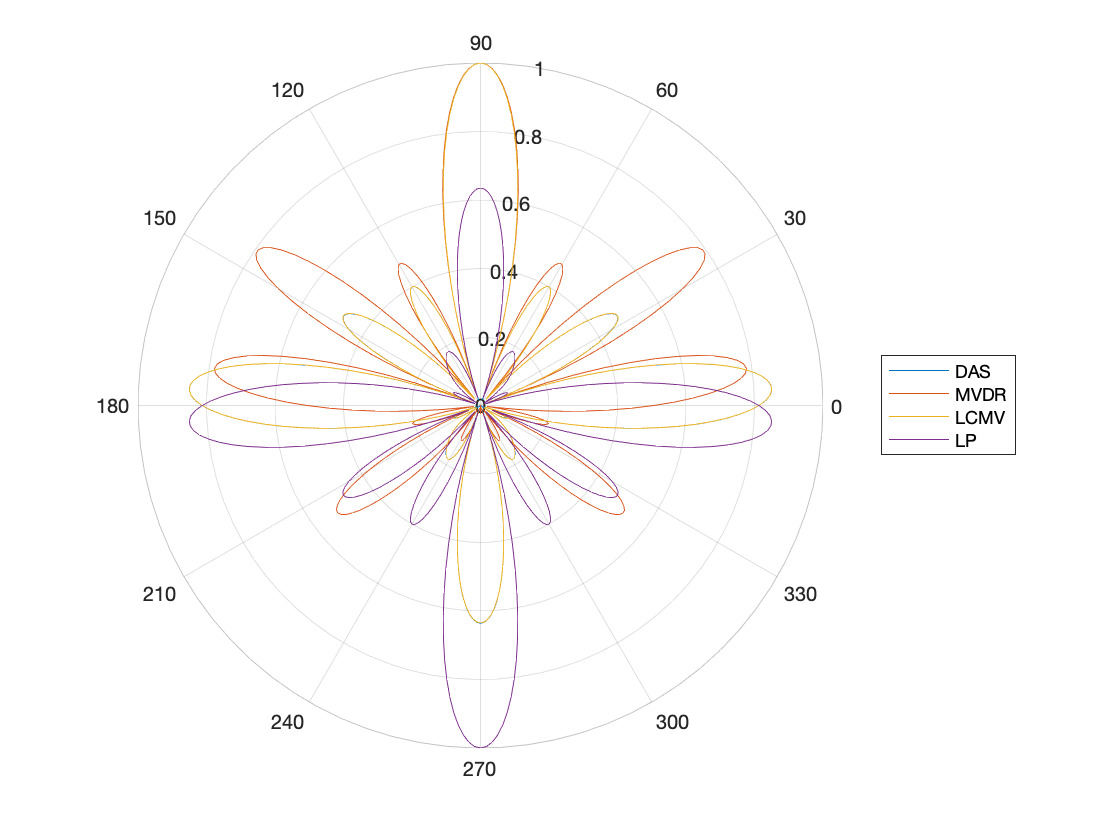

% plot beamform patterns
ebi = steeringVector(m_xPos, m_yPos, m_zPos, fc, c, incidentAngle(1), incidentAngle(2));
ebi = reshape(ebi, 1, 1, 8); 
w_DAS = weightingVectorDAS(ebi); 
w_MVDR = weightingVectorMVDR(x.', ebi);
w_LCMV = weightingVectorLCMV(x.');
w_LP = weightingVectorLP(x.');
AF_DAS = arrayFactor(w_DAS, escan);
AF_MVDR = arrayFactor(w_MVDR, escan);
AF_LCMV = arrayFactor(w_LCMV, escan);
AF_LP = arrayFactor(w_LP, escan);
polarplot(deg2rad(thetaScanningAngles),AF_DAS')
hold on
polarplot(deg2rad(thetaScanningAngles),AF_MVDR')
polarplot(deg2rad(thetaScanningAngles),AF_LCMV')
polarplot(deg2rad(thetaScanningAngles),AF_LP')
hold off
legend(["DAS", "MVDR", "LCMV", "LP"])

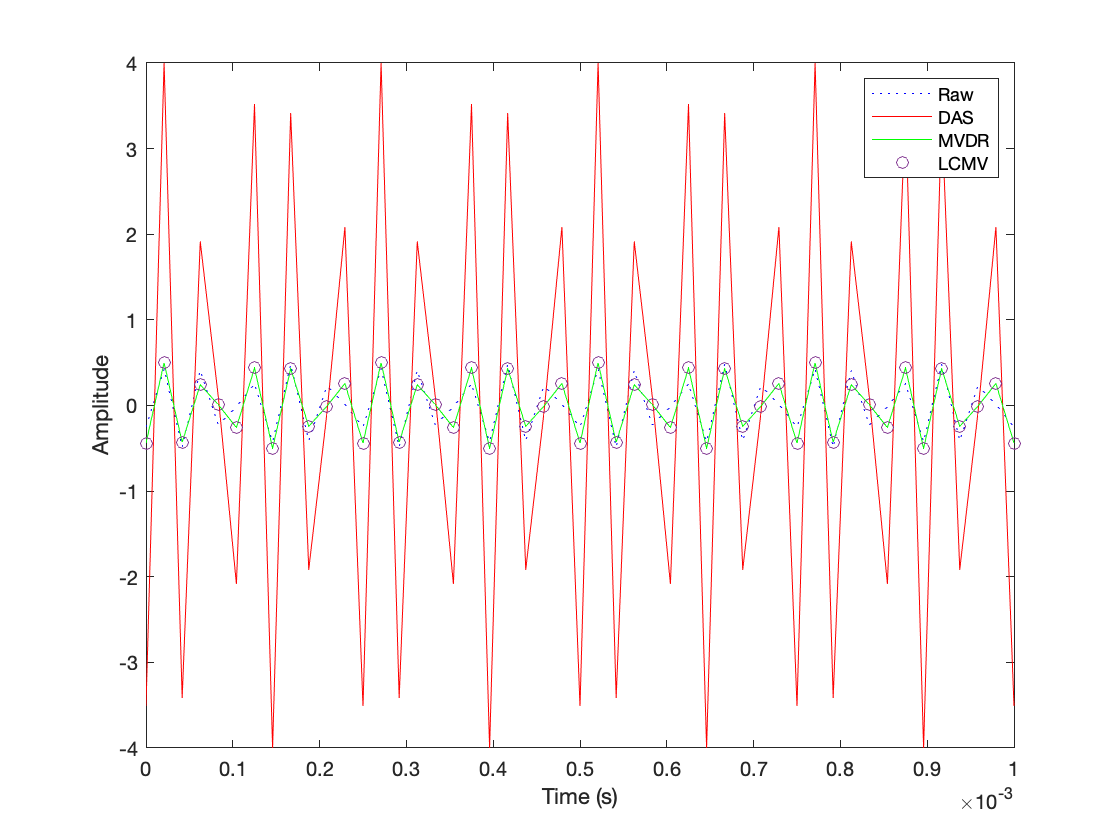

% Beamforming
y_DAS = x*squeeze(w_DAS);
y_MVDR = x*squeeze(w_MVDR);
y_LCMV = x*squeeze(w_LCMV);
y_LP = x*squeeze(w_LP);
figure;
plot(t,real(x(:,2)),'b:',t,real(y_DAS),'r', t, real(y_MVDR), 'g', t, real(y_MVDR), 'o');
xlim([0 0.001]);
xlabel('Time (s)')
ylabel('Amplitude')
legend('Raw','DAS','MVDR', "LCMV", "LP")

% calculate array gain 
snr_raw = snr(real(x(:,2)), noise(:,2))

snr_raw = 1.0692

snr_DAS = snr(real(y_DAS), noise(:,2))

snr_DAS = 19.4501

snr_MVDR = snr(real(y_MVDR), noise(:,2))

snr_MVDR = 1.4040

snr_LCMV = snr(real(y_LCMV), noise(:,2))

snr_LCMV = 19.5988

snr_LP = snr(real(y_LP), noise(:,2))

snr_LP = 15.6170